To investigate the detection of bout

load(fullfile(getpath('result'),'tail_pca'));

[sessionID,fishID] = getfish();
numFish = length(sessionID);
numBout_fish =zeros(numFish,1);
single_bout_len = [];
for iFish=1:numFish
    load(fullfile(getpath('behavior',sessionID{iFish},fishID{iFish}),'tail_swing'),'bout_idx');
    numBout_fish(iFish) = length(bout_idx);
    single_bout_len = [single_bout_len;bout_idx(:,2)-bout_idx(:,1)];
end
cumnumBout_fish = cumsum(numBout_fish);

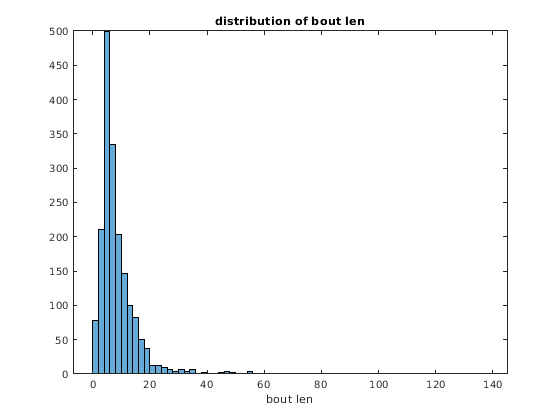

figure,
histogram(single_bout_len,'BinWidth',1);
title('distribution of bout len');
xlabel('bout len');

Due to too many 2-frame bouts from above, let's check those bouts are true or not. First we need to find the location of those bouts. and then plot them.

short_bout = find(single_bout_len==2);
boutID_in_fish = zeros(length(short_bout),1);
fishID_in_bout = boutID_in_fish;
%which fish has this short bout at what time
for i = 1:length(short_bout)
    fishID_in_bout(i) = find((short_bout(i) - cumnumBout_fish)<0,1,'first');
    boutID_in_fish(i) = short_bout(i) - sum(numBout_fish(1:fishID_in_bout-1));
end
%plot its curv change at this time

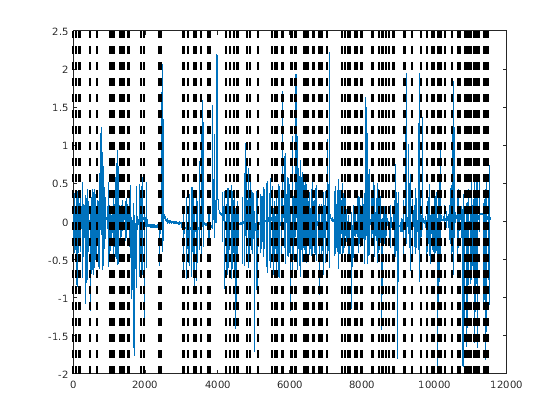

load(fullfile(getpath('behavior',sessionID{1},fishID{1}),'tail_swing'),'sum_curv','bout_idx');
figure,
plot(sum_curv);hold on;
mark_line(gca,bout_idx(boutID_in_fish(fishID_in_bout==1),1));